clear all;
fs=8000;
mas=[26 31 24 ];%коды фонем в тестовом сигнале
% mas=12;
fft_size=512;
numcf=15;%количество MFCC коэффициентов
t=0:1/fs:599*1/fs;
f=[2093 293 659 1396 196];% массив частот (5 частот)

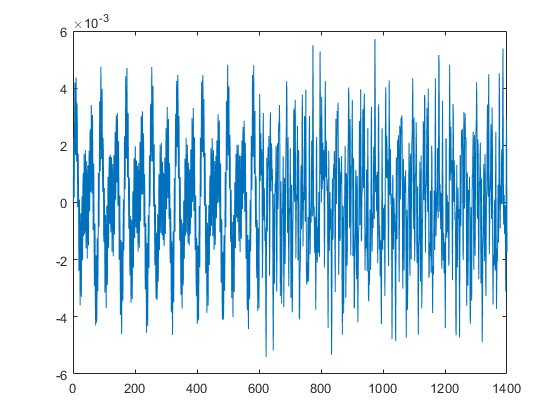

% SP=GSS_generation(t,f,mas);
SP_out=GSS_generation(t,f,mas);

SP=[SP_out(:,1);SP_out(1:200,2);SP_out(:,3)];
plot(SP);

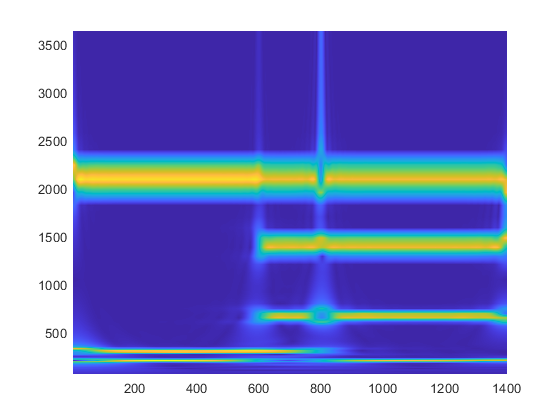

[WT,frq]=cwt(SP,'bump',fs);
WT_abs=abs(WT);
WT_mean=mean(WT_abs,1);
t=1:size(SP,1);
pcolor(t,frq,WT_abs);
shading interp;

[pks,locs] = findpeaks(WT_mean);
% value_por=mean(WT_mean);
% value_por=2e-3;
% WT_res(abs(WT_res)<value_por)=0;

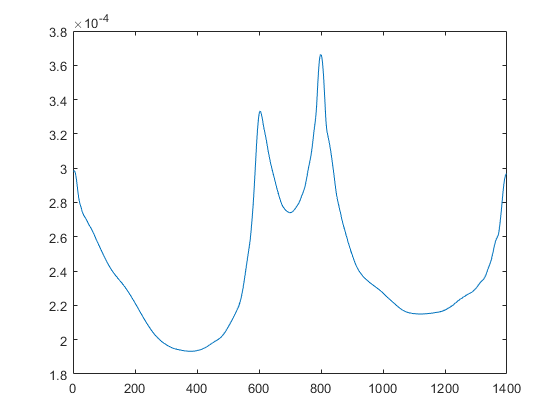

plot(WT_mean);